% Autor: Luis Eduardo Arenas Deseano
% Proyecto: Sistemas Inteligentes
% Descripción: Probabilidad posterior con SVM
% Fecha: 1/12/2024

load fisheriris
classKeep = ~strcmp(species,'virginica');
X = meas(classKeep,3:4);
y = species(classKeep);

SVMModel = fitcsvm(X,y,'ClassNames',{'setosa','versicolor'});

rng(1); % For reproducibility
[SVMModel,ScoreParameters] = fitPosterior(SVMModel); 

ScoreParameters

ScoreParameters = struct with fields:
                        Type: 'step'
                  LowerBound: -0.8431
                  UpperBound: 0.6897
    PositiveClassProbability: 0.5000


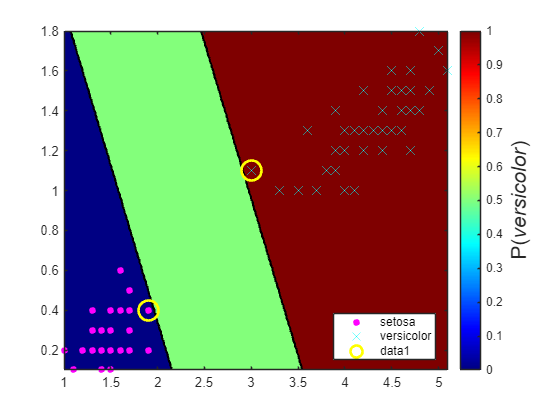


xMax = max(X);
xMin = min(X);
d = 0.01;
[x1Grid,x2Grid] = meshgrid(xMin(1):d:xMax(1),xMin(2):d:xMax(2));

[~,PosteriorRegion] = predict(SVMModel,[x1Grid(:),x2Grid(:)]);

figure;
contourf(x1Grid,x2Grid,...
        reshape(PosteriorRegion(:,2),size(x1Grid,1),size(x1Grid,2)));
h = colorbar;
h.Label.String = 'P({\it{versicolor}})';
h.YLabel.FontSize = 16;
colormap jet;

hold on
gscatter(X(:,1),X(:,2),y,'mc','.x',[15,10]);
sv = X(SVMModel.IsSupportVector,:);
plot(sv(:,1),sv(:,2),'yo','MarkerSize',15,'LineWidth',2);
axis tight
hold off